# Load data

clear;clc;


% %% Silica
% wavenumbers_si=[12739,12219] % 785nm and raman shift of silica
% % CCD
% threshold_si=1800;
% [peaks, peak_indices] = findpeaks(spectrum, 'MinPeakHeight', threshold_si);
% experimental_pixels = peak_indices;
% experimental_wavenumbers_cm1 = [wavenumbers_si(1), wavenumbers_si(2)];

## Wavenumbers above 785nm

% % First 785nm Last 922.450
% hgar_nm=[785.000, 794.818, 800.616, 811.531, 826.452, 842.465, 852.144, 866.794, 912.297, 922.450];
% 
% % Wavenumbers=1./hgar_nm;
% wavenumbers_hgar=[12738.854,12579.099,12485.160,12330.679,12100.967,11851.487,11727.270,11539.902,10947.458,10836.863]; 

hgar_nm=[785.000, 852.144, 866.794, 912.297, 922.450]; % peaks in nm

% Wavenumbers=1./hgar_nm;
wavenumbers_hgar=[12738.854, 11727.270, 11536.766, 10947.458, 10836.863];  % selected peaks in wavenumbers
%Raman shifts
% shifts=((785)^(-1) - (raman_spec_ref_peak).^(-1))*10^7;


% CCD
%% Load
data=load('c.mat');

data=data.data.ItemsData(1,1);
spectrum=data{1,1};
%Intensity
threshold_si=1644;
%Findpeaks
[peaks, peak_indices] = findpeaks(spectrum, 'MinPeakHeight', threshold_si);

experimental_pixels = [5,449,551,885,965]; % selected pixels
experimental_wavenumbers_cm1 = wavenumbers_hgar;


## Fit a polynomial

degree = 2;
p = polyfit(  experimental_pixels,experimental_wavenumbers_cm1, degree);

% Use the calibrated polynomial for a new sample (replace with actual data)
pixel_range = linspace(1, 1044, 1044); % Assuming full range of pixels

adjusted_wavenumber_axis = polyval(p, pixel_range); %fliplr(x) might be used

adjusted_wavenumbers_axis=12738.854-adjusted_wavenumber_axis;


## Save calibration

% Define the file path
file_path = 'QePro_NIR_spectrum_axis2.txt';

% Open the file for writing
fileID = fopen(file_path, 'w');

% Check if the file was opened successfully
if fileID == -1
    error('Could not open file for writing');
end

% Write each element of the array to the file
for i = 1:length(adjusted_wavenumbers_axis)
    fprintf(fileID, '%f\n', adjusted_wavenumbers_axis(i));
end


## Plots

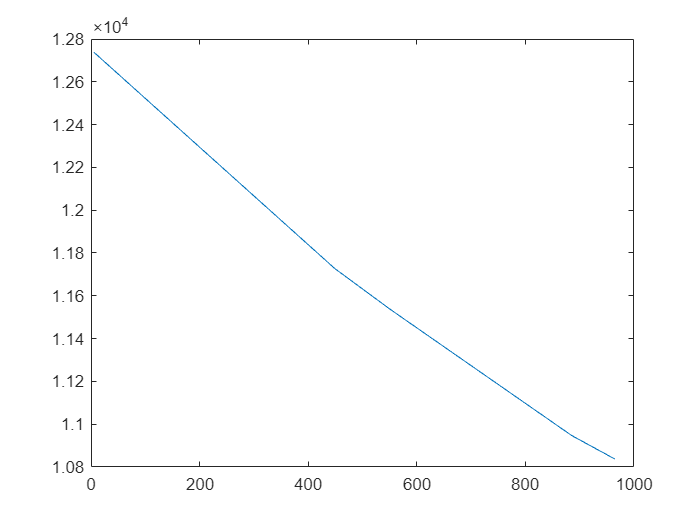

% Plot 1
figure;
plot(experimental_pixels,wavenumbers_hgar);

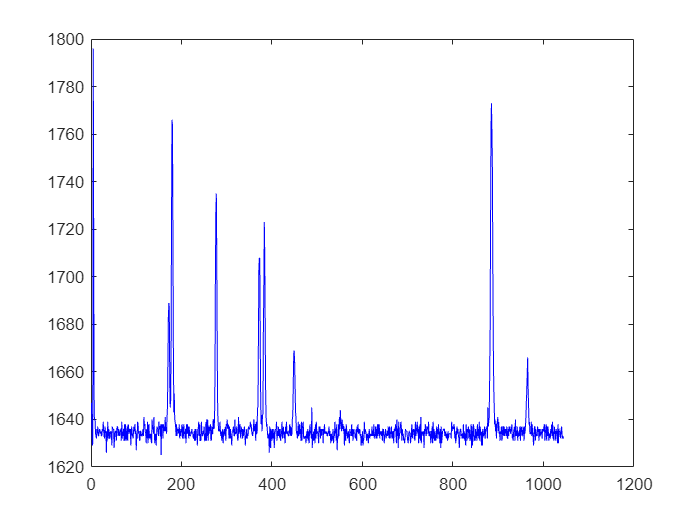


% Plot 2
figure;
plot(spectrum, 'b');

% % find position of peaks
% thresh=1780;
% [~, indices]=findpeaks(spectrum, 'MinPeakHeight', thresh);

Error using spectrum
SPECTRUM has been deprecated. Use PSPECTRUM or PERIODOGRAM instead.

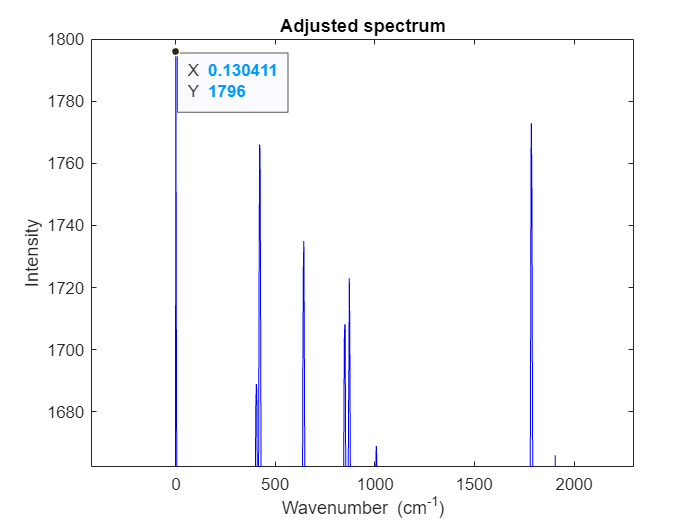


% Plot 3
figure;
plot(adjusted_wavenumbers_axis', spectrum', 'b');
xlabel('Wavenumber (cm^{-1})');
ylabel('Intensity');
title('Adjusted spectrum');


% xlim([-50 2000])
% ylim([1620 1800])


## testing- with silica

clear;clc;

%load calibrated axis
axiss=load('QePro_NIR_spectrum_axis1.txt');

%load cartilage data
data1=load('silica_2_flip_2.mat');

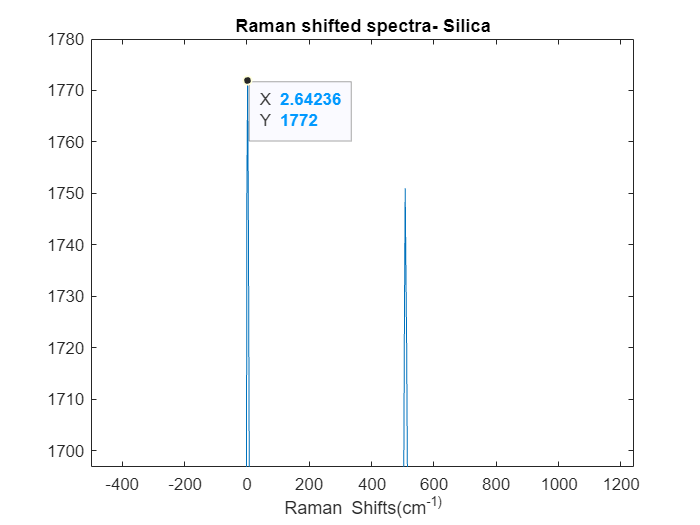

data1=data1.data.ItemsData(1,1);
data1=data1{1,1};
% 3D data
data1=squeeze(data1);
spectrum_si=data1';
% %view image
% figure;imagesc(data(:,:,500));
% get any spectrum
% spectrum_cart=squeeze(data1(100,32,:));

%plot calibrated spectrum
figure;
plot(axiss',spectrum_si');
title('Raman shifted spectra- Silica');
xlabel('Raman Shifts(cm^-1)')

## with cartilage


%load cartilage data
data2=load('cartilage_sample_1_62x252_1s.mat');

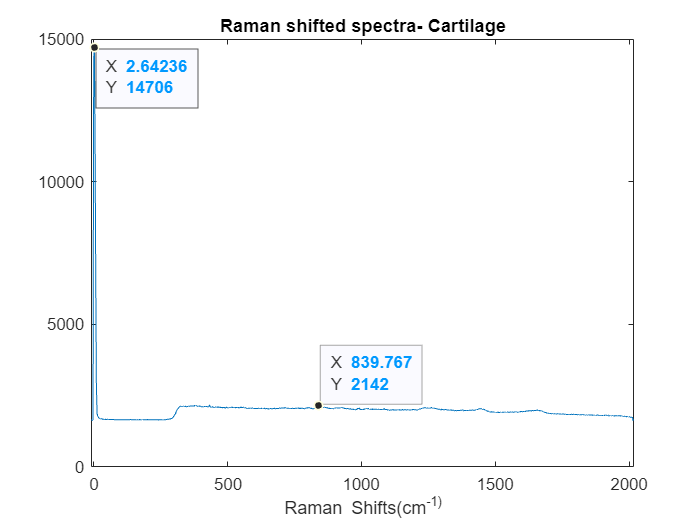

data2=data2.data.ItemsData(1,1);
data2=data2{1,1};
% 3D data
data2=squeeze(data2(100,32,:));
spectrum_cart=data2';
% %view image
% figure;imagesc(data(:,:,500));
% get any spectrum
% spectrum_cart=squeeze(data1(100,32,:));

%plot calibrated spectrum
figure;
plot(axiss',spectrum_cart);
title('Raman shifted spectra- Cartilage');
xlabel('Raman Shifts(cm^-1)')
xlim([0 2000])

ax = gca;
chart = ax.Children(1);
datatip(chart,839.8,2142);